# Create Simple Deep Learning Network for Classification

This example shows how to create and train a simple convolutional neural network for deep learning classification. Convolutional neural networks are essential tools for deep learning, and are especially suited for image recognition.

The example demonstrates how to: 

- Load and explore image data.

- Define the network architecture.

- Specify training options.

- Train the network.

- Predict the labels of new data and calculate the classification accuracy.

## Load and Explore Image Data

Load the digit sample data as an image datastore. `imageDatastore` automatically labels the images based on folder names and stores the data as an `ImageDatastore` object. An image datastore enables you to store large image data, including data that does not fit in memory, and efficiently read batches of images during training of a convolutional neural network.

digitDatasetPath = fullfile('C:/Users/smart/Documents/GitHub/412/A4', 'orl_faces\');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

Display some of the images in the datastore.

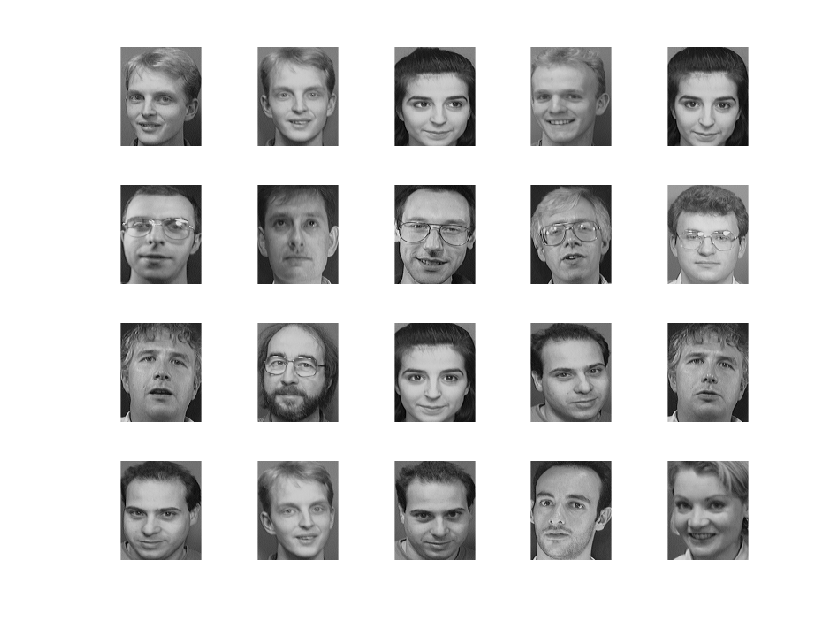

figure;
perm = randperm(400,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

Calculate the number of images in each category. `labelCount` is a table that contains the labels and the number of images having each label. The datastore contains 1000 images for each of the digits 0-9, for a total of 10000 images. You can specify the number of classes in the last fully connected layer of your network as the `OutputSize` argument.

labelCount = countEachLabel(imds)

labelCount = 40×2 table
    Label    Count
    _____    _____

     s1       10  
     s10      10  
     s11      10  
     s12      10  
     s13      10  
     s14      10  
     s15      10  
     s16      10  
     s17      10  
     s18      10  
     s19      10  
     s2       10  
     s20      10  
     s21      10  
     s22      10  
     s23      10  


You must specify the size of the images in the input layer of the network. Check the size of the first image in `digitData`. Each image is 28-by-28-by-1 pixels.

img = readimage(imds,1);
size(img)

ans =    112    92


## Specify Training and Validation Sets

Divide the data into training and validation data sets, so that each category in the training set contains 750 images, and the validation set contains the remaining images from each label. `splitEachLabel` splits the datastore `digitData` into two new datastores, `trainDigitData` and `valDigitData`.

numTrainFiles = 5;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

## Define Network Architecture

Define the convolutional neural network architecture.

layers = [
    imageInputLayer([112 92 1])
    
    convolution2dLayer(3,8,'Padding',1)
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding',1)
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding',1)
    reluLayer
    
    fullyConnectedLayer(40)
    softmaxLayer
    classificationLayer];

**Image Input Layer** An [docid:nnet_ref.mw_fcd2d9b1-ce25-49d1-9d06-b7cf41594ff4](docid:nnet_ref.mw_fcd2d9b1-ce25-49d1-9d06-b7cf41594ff4) is where you specify the image size, which, in this case, is 28-by-28-by-1. These numbers correspond to the height, width, and the channel size. The digit data consists of grayscale images, so the channel size (color channel) is 1. For a color image, the channel size is 3, corresponding to the RGB values. You do not need to shuffle the data because `trainNetwork`, by default, shuffles the data at the beginning of training.

**Convolutional Layer** In the convolutional layer, the first argument is `filterSize`, which is the height and width of the filters the training function uses while scanning along the images. In this example, the number 3 indicates that the filter size is 3-by-3. You can specify different sizes for the height and width of the filter. The second argument is the number of filters, `numFilters`, which is the number of neurons that connect to the same region of the input. This parameter determines the number of feature maps. Use the `'Padding'` name-value pair to add padding to the input feature map. For a filter size of 3, a padding of 1 ensures that the spatial output size is the same as the input size. You can also define the `Stride` and learning rates for this layer using name-value pair arguments of [docid:nnet_ref.mw_2d97b6cd-f8aa-4fad-88d6-d34875484820](docid:nnet_ref.mw_2d97b6cd-f8aa-4fad-88d6-d34875484820).

**Batch Normalization Layer** Batch normalization layers normalize the activations and gradients propagating through a network, making network training an easier optimization problem. Use batch normalization layers between convolutional layers and nonlinearities, such as ReLU layers, to speed up network training and reduce the sensitivity to network initialization. Use [docid:nnet_ref.mw_b7913af4-3a40-4020-bb2c-18c946f5eadd](docid:nnet_ref.mw_b7913af4-3a40-4020-bb2c-18c946f5eadd) to create a batch normalization layer.

**ReLU Layer** The batch normalization layer is followed by a nonlinear activation function. The most common activation function is the rectified linear unit (ReLU). Use [docid:nnet_ref.mw_ca5427bd-5cdc-4a58-ba63-302c257d8222](docid:nnet_ref.mw_ca5427bd-5cdc-4a58-ba63-302c257d8222) to create a ReLU layer.

**Max Pooling Layer** Convolutional layers (with activation functions) are sometimes followed by a down-sampling operation that reduces the spatial size of the feature map and removes redundant spatial information. Down-sampling makes it possible to increase the number of filters in deeper convolutional layers without increasing the required amount of computation per layer. One way of down-sampling is using a max pooling, which you create using  [docid:nnet_ref.mw_d2785483-a560-4276-a1c0-daa5f58a1d4b](docid:nnet_ref.mw_d2785483-a560-4276-a1c0-daa5f58a1d4b). The max pooling layer returns the maximum values of rectangular regions of inputs, specified by the first argument, `poolSize`. In this example, the size of the rectangular region is [2,2]. The `'Stride'` name-value pair argument specifies the step size that the training function takes as it scans along the input.

**Fully Connected Layer** The convolutional and down-sampling layers are followed by one or more fully connected layers. As its name suggests, a fully connected layer is a layer in which the neurons connect to all the neurons in the preceding layer. This layer combines all the features learned by the previous layers across the image to identify the larger patterns. The last fully connected layer combines the features to classify the images. Therefore, the `OutputSize` parameter in the last fully connected layer is equal to the number of classes in the target data. In this example, the output size is 10, corresponding to the 10 classes. Use [docid:nnet_ref.mw_1e7fbc56-4746-4f30-8cd9-7048ce806a0d](docid:nnet_ref.mw_1e7fbc56-4746-4f30-8cd9-7048ce806a0d) to create a fully connected layer.

**Softmax Layer** The softmax activation function normalizes the output of the fully connected layer. The output of the softmax layer consists of positive numbers that sum to one, which can then be used as classification probabilities by the classification layer. Create a softmax layer using the [docid:nnet_ref.mw_a09d3c68-d062-4692-a950-9a7fea5c40c3](docid:nnet_ref.mw_a09d3c68-d062-4692-a950-9a7fea5c40c3) function after the last fully connected layer.

**Classification Layer** The final layer is the classification layer. This layer uses the probabilities returned by the softmax activation function for each input to assign the input to one of the mutually exclusive classes and compute the loss. To create a classification layer, use [docid:nnet_ref.bu5lho8](docid:nnet_ref.bu5lho8).

## Specify Training Options

After defining the network structure, specify the training options. Set the maximum number of epochs to 4. An epoch is a full training cycle on the entire training data set. Start training with an initial learning rate of 0.01. Monitor the network accuracy during training by specifying validation data and validation frequency. The software trains the network on the training data and calculates the accuracy on the validation data at regular intervals during training. The validation data is not used to update the network weights. Turn on the training progress plot, and turn off the command window output.

options = trainingOptions('sgdm', ...
    'MaxEpochs',100, ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

## Train Network Using Training Data

Train the network using the architecture defined by `layers`, the training data, and the training options. By default, `trainNetwork` uses a GPU if one is available (requires Parallel Computing Toolbox™ and a CUDA® enabled GPU with compute capability 3.0 or higher). Otherwise, it uses a CPU. You can also specify the execution environment by using the `'ExecutionEnvironment'` name-value pair argument of `trainingOptions`.

The training progress plot shows the mini-batch loss and accuracy and the validation loss and accuracy. For more information on the training progress plot, see [docid:nnet_examples.mw_507458b6-14c3-4a31-884c-9f2119ff7e05](docid:nnet_examples.mw_507458b6-14c3-4a31-884c-9f2119ff7e05). The loss is the [cross-entropy loss](docid:nnet_ref.bu80p30-3). The accuracy is the percentage of images that the network classifies correctly.

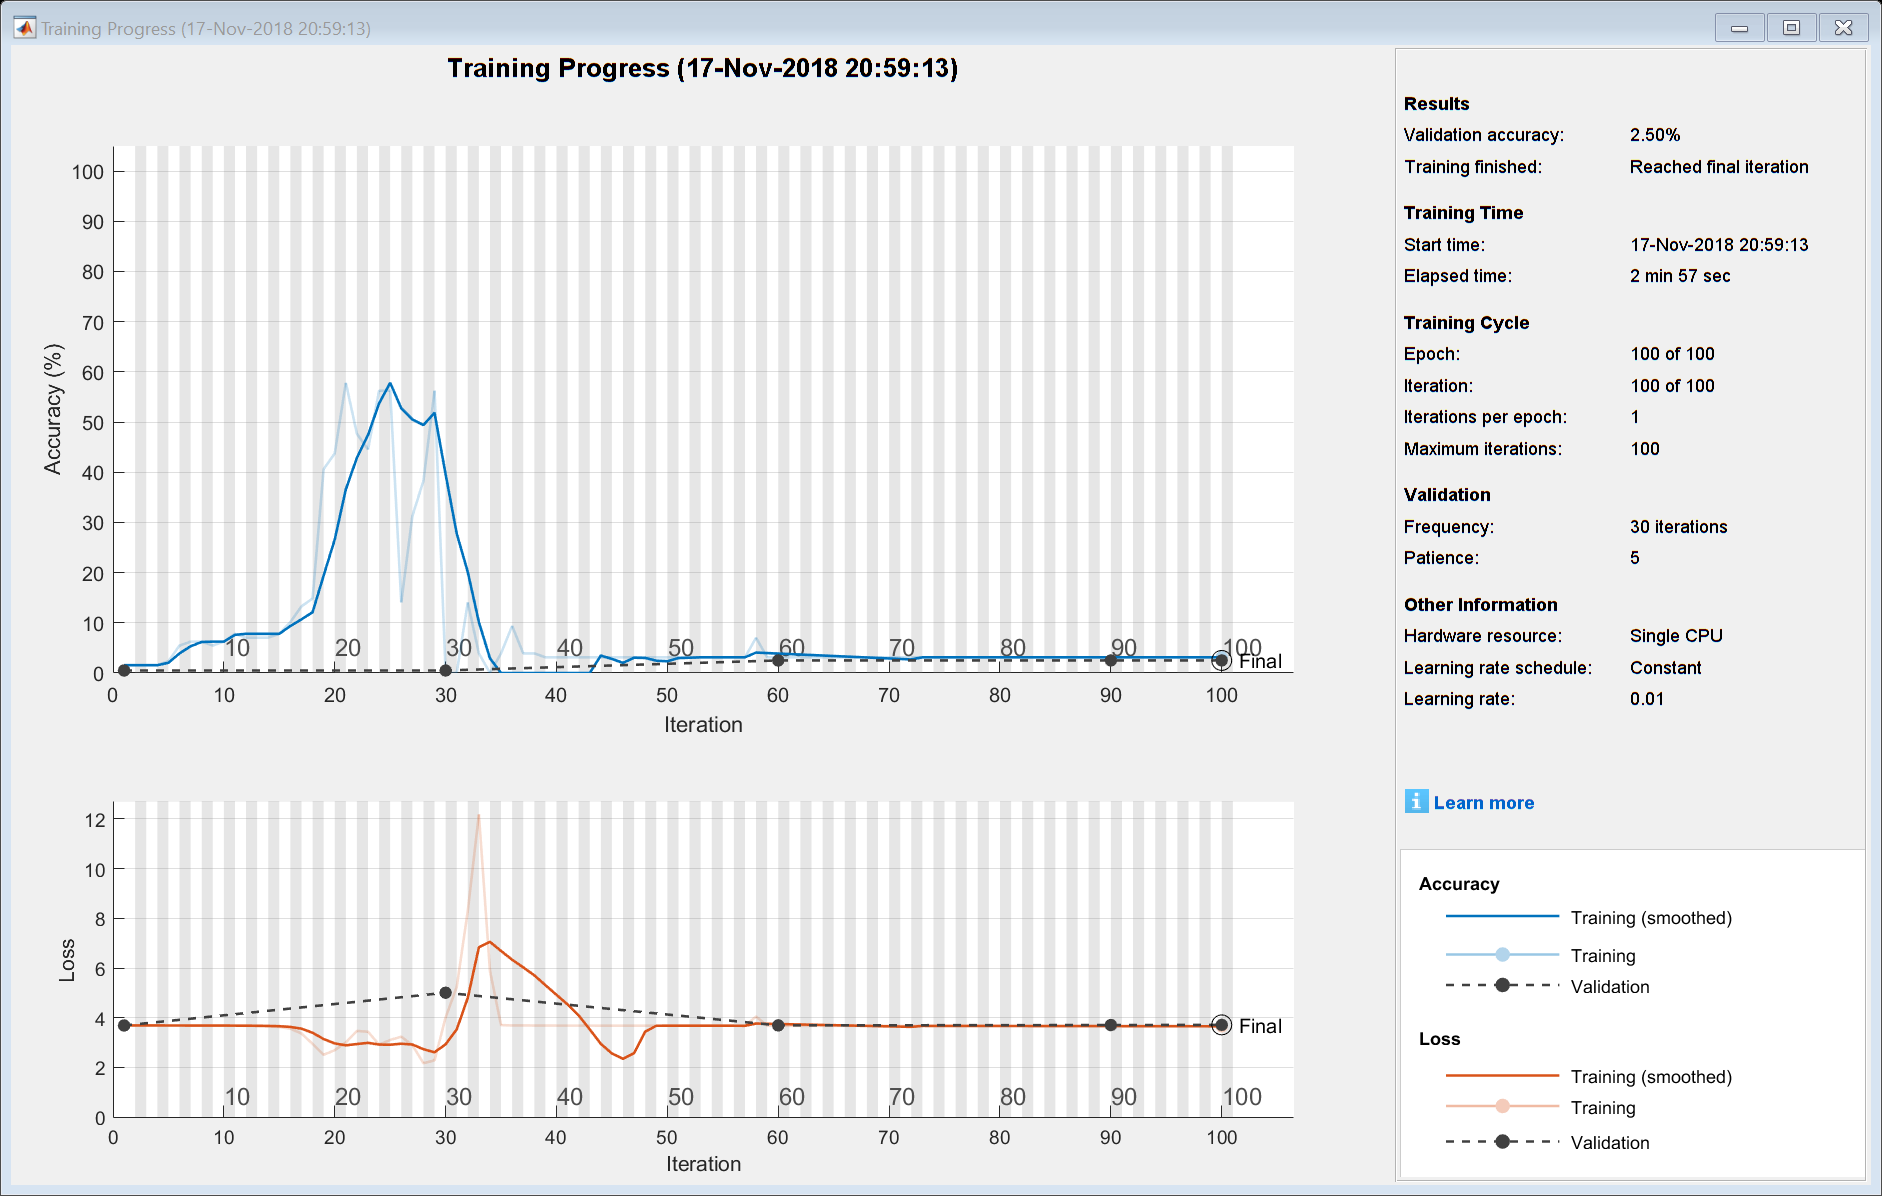

net = trainNetwork(imdsTrain,layers,options);

## Classify Validation Images and Compute Accuracy

Predict the labels of the validation data using the trained network, and calculate the final validation accuracy. Accuracy is the fraction of labels that the network predicts correctly. In this case, more than 99% of the predicted labels match the true labels of the validation set.

YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.0250